# Display_branchCurrents.mlx

## This script will display precalculated analyses of grid parameters.

#### This script changes all interpretation parameters to LaTeX.

list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end

tic
folder_name = 'saved_outputs/'; %subfolder where data will be stored

system_name = 'ieee9'

system_name = 'ieee9'


tableName = strcat(folder_name, 'nominalValuesTable_',...
    system_name, '.csv');

nominalValuesTable = readtable(tableName);

branchesToPlot = 3;
% branchesToPlot = [1 2 3 4 5 6 7 8 9];
% branchesToPlot = [4 5 6];

sampling_rate = nominalValuesTable.sampling_rate

sampling_rate = 0.0100

T = nominalValuesTable.T

T = 3

W = nominalValuesTable.W

W = 300


currentsArrName = strcat(folder_name,'currents_', ...
    system_name, '.mat');
currentsArr = load(currentsArrName);
currentsArr = currentsArr.currentsArr;

bifurcationIdx = size(currentsArr,1)

bifurcationIdx = 10724

indicesToPlotTruncated = 1:bifurcationIdx;
xaxisTruncated = (bifurcationIdx - indicesToPlotTruncated)...
    *sampling_rate/(60);

#### Subplot 1: Currents  obtained from the original run.

figure('Name', 'Complete Analysis of Branch currents.');
subplot(2,3,1);
plot(xaxisTruncated, currentsArr(:, branchesToPlot));
set(gca,'xdir','reverse')
title('Branch Currents ');
xlabel('Time to Bifucation (min)');
ylabel('Currents Flow Magnitude (A)');

name_labelcurrents = strcat(folder_name, 'labelcurrents_'...
    , system_name, '.mat');
labelcurrents = load(name_labelcurrents, "labelcurrents");
labelcurrents = labelcurrents.labelcurrents;
legend(labelcurrents(branchesToPlot))

#### Subplot 2: Sp1 (Subplot 1) Currents  passed thru GKS filter.

subplot(2,3,2);

gks_currentsArr = load(strcat(folder_name, 'gks_currents_', ...
    system_name, '.mat'), 'gks_currentsArr');
gks_currentsArr = gks_currentsArr.gks_currentsArr;

convolutionMargin = floor(bifurcationIdx*0.005)

convolutionMargin = 53

indicesToPlotPostConvolution = 1+convolutionMargin:bifurcationIdx-W+1;
xaxisPostConvolution = (bifurcationIdx - indicesToPlotPostConvolution)...
    *sampling_rate/(60);
plot(xaxisPostConvolution, ...
    gks_currentsArr(indicesToPlotPostConvolution,branchesToPlot));
set(gca,'xdir','reverse')

title(' Branch Currents after being passed thru GKS filter (A)');
xlabel('Time to Bifucation (min)');
ylabel('Currents  Magnitude (A)');

name_labelGKScurrents = strcat(folder_name, 'labelGKScurrents_'...
    , system_name, '.mat');
labelGKScurrents = load(name_labelGKScurrents, "labelGKScurrents");
labelGKScurrents = labelGKScurrents.labelGKScurrents;
legend(labelGKScurrents(branchesToPlot))

#### Subplot 3: Sp1 Currents  - Sp2 Currents  are displayed.

subplot(2,3,3);

currentsDetrendedArrName = ...
    strcat(folder_name,'currentsDetrended_', ...
    system_name, '.mat');
currentsDetrendedArr = ...
    load(currentsDetrendedArrName,'currentsDetrendedArr');
currentsDetrendedArr = ...
    currentsDetrendedArr.currentsDetrendedArr;

plot(xaxisPostConvolution, ...
    currentsDetrendedArr(:, branchesToPlot));

set(gca,'xdir','reverse')
title({['Detrended Currents  after subtracting '] ...
    ['the GKS signal from the original (A)']});
xlabel('Time to Bifucation (min)');
ylabel('Detrended currents (A)');

name_labelDeltacurrents = strcat(folder_name, 'labelDeltacurrents_'...
    , system_name, '.mat');
labelDeltacurrents = load(name_labelDeltacurrents, "labelDeltacurrents");
labelDeltacurrents = labelDeltacurrents.labelDeltacurrents;

#### Subplot 4: AR1(Sp3 Currents )

ar1_vector = ...
    load(strcat(folder_name,'ar1_vector_currents_', ...
    system_name, '_', num2str(T), '_sec.mat'),'ar1_vector');

ar1_vector = ar1_vector.ar1_vector;

indicesToPlotPostParametrization = 1+convolutionMargin:bifurcationIdx-2*W+1;
xaxisPostParametrization = (bifurcationIdx - indicesToPlotPostParametrization)...
    *sampling_rate/(60);

subplot(2,3,4)
plot(xaxisPostParametrization, ar1_vector(:, branchesToPlot));
% yyaxis left
set(gca,'xdir','reverse')
xlabel3 = xlabel('Time to bifurcation (minutes)');
% yticks3 = yticks;
ylabel3 = ylabel('$a_1$');
% ylabel3.Color = colors(1,:);
title('Autocorrelation values');

name_labelARDeltacurrents = strcat(folder_name, 'labelARDeltacurrents_'...
    , system_name, '.mat');
labelARDeltacurrents = ...
    load(name_labelARDeltacurrents, "labelARDeltacurrents");
labelARDeltacurrents = labelARDeltacurrents.labelARDeltacurrents;
legend(labelARDeltacurrents(branchesToPlot))

#### Subplot 5: Var(Sp3 Currents )

var_vector = ...
    load(strcat(folder_name,'var_vector_currents_', ...
    system_name, '_', num2str(T), '_sec.mat'), 'var_vector');

var_vector = var_vector.var_vector;

subplot(2,3,5)
plot(xaxisPostParametrization, var_vector(:, branchesToPlot));
% yyaxis left
set(gca,'xdir','reverse')
% yyaxis right
ylabel4 = ylabel('$\sigma^2$');
% ylabel4.Color = colors(2,:);
% yticks4 = yticks;
% set(gca,'ycolor',colors(2,:))
% set(gca,'xdir','reverse')
xlabel4 = xlabel('Time to bifurcation (minutes)');
title('Variance values');

name_labelVarDeltacurrents = strcat(folder_name, 'labelVarDeltacurrents_'...
    , system_name, '.mat');
labelVarDeltacurrents =...
    load(name_labelVarDeltacurrents, "labelVarDeltacurrents");
labelVarDeltacurrents = labelVarDeltacurrents.labelVarDeltacurrents;
legend(labelVarDeltacurrents(branchesToPlot))

#### Print the figure.

pdf_location_name = 'pdf/'

pdf_location_name = 'pdf/'

if T < 1
    windowInSec = strcat('point',string(10*T),'_sec');
else
    windowInSec = strcat(string(T),'_sec');
end
imagePdfName = strcat(pdf_location_name, '_', system_name,...
    'branchcurrents_',num2str(branchesToPlot),'_T_',windowInSec)

imagePdfName = "pdf/_ieee9branchcurrents_3_T_3_sec"

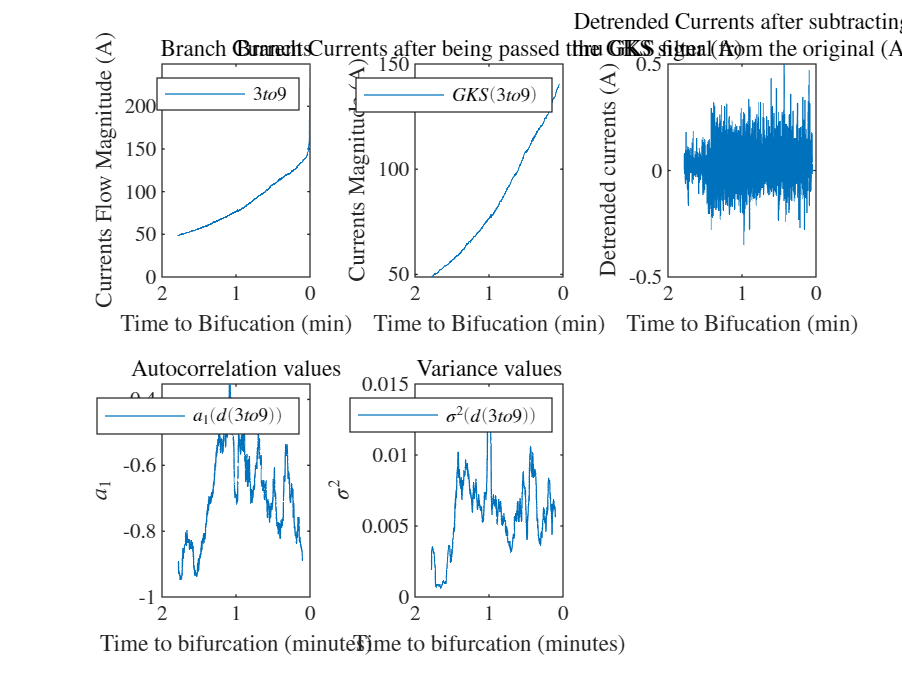


set(gcf, 'PaperSize', [24 12]); %set the paper size to what you want  
print(imagePdfName,'-dpdf', '-fillpage') % then print it